# Crank-Nicolson Solution to the Heat-Conduction Equation

% * Engineering Analysis Format (EAF)
% 
%the above * create a bullet item
% Emmanuel Rodriguez
% June 23, 2021, @the Ranch, Fort Hancock, TX
%
% Refer to Chapra, Ex. 30.1, p.843 and Ex 30.3, p. 850
% * Accompanies hand written notes 'Solving PDEs via Numerical Methods
% Finite Diff.: Parabolic Eqs.pdf' 
% location: C:\Users\ejoaq\OneDrive\1 My_Notebook\2 Entrepreneurship and Work\2 Freelance\Programming Logic and Design jobs\MATLAB Fourier Transform Modeling - Shahrooz

## Start

## Step 1: Mathematical Modeling

Problem Statement

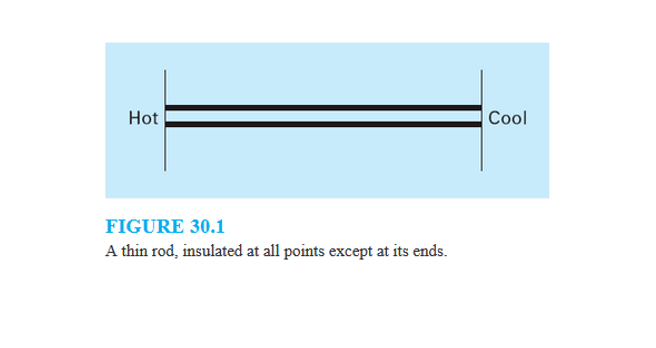

% Consider a thin rod insulated at all points except the ends, find the
% solution the heat condution equation.
% The solution will consist of a series of spatial distributions
% corresponding to the state of the element at various times.
%
figure;
imshow('fig30.1.png'); % System model, thin rod with BCs

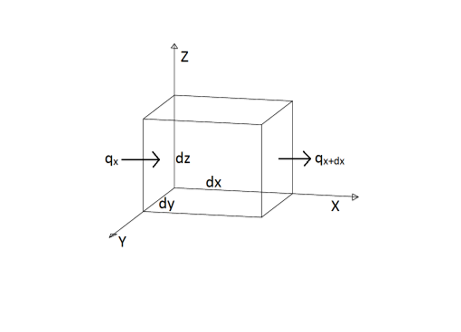

imshow('heat_diff_element.png'); % differential element with heat input/output


% when creating a new section with double percent symbol, make sure to...
% leave a space after the percent

## Step 2: Derivation of Governing Equations

Fourier's Law of heat conduction

Heat Conduction Equation (one dimensional):


$$\frac {\partial{T}} {\partial{t}} = k \frac{ \partial^2T} {\partial x^2}$$


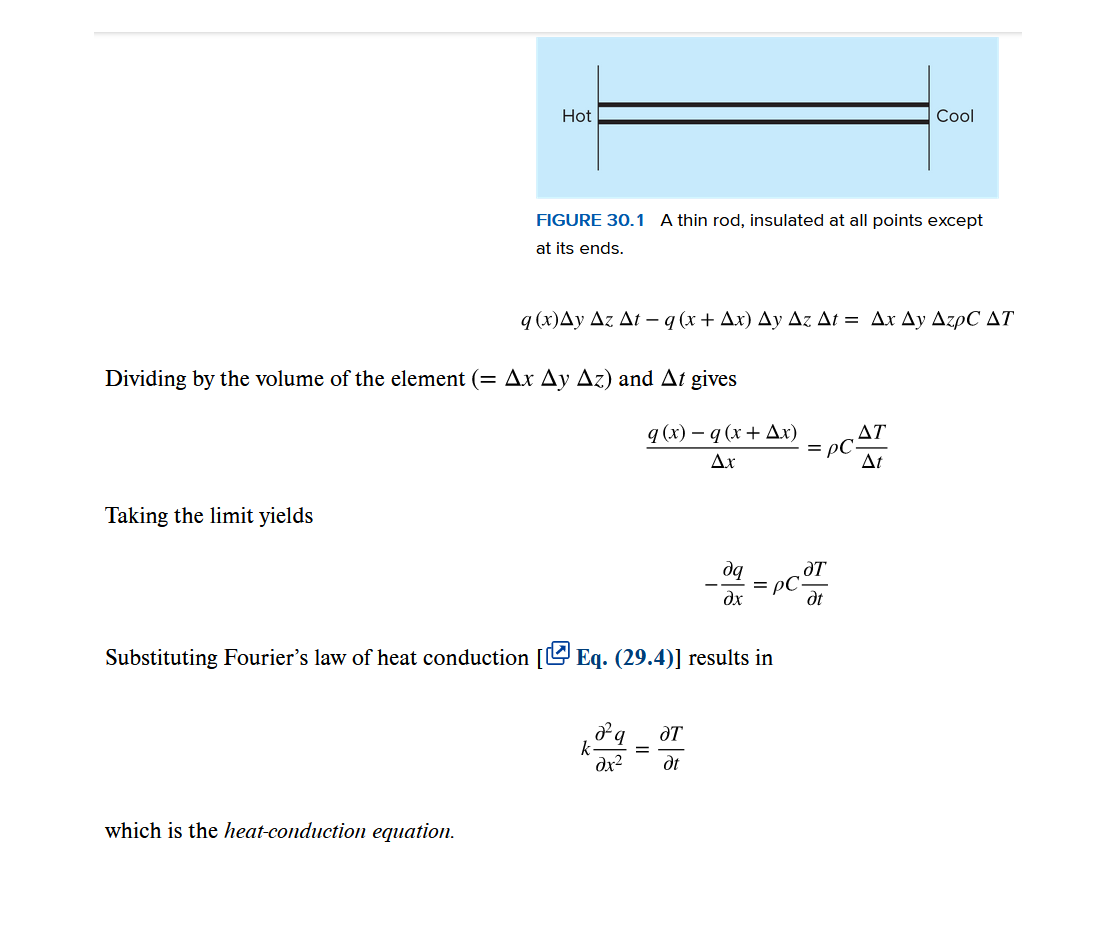

imshow("heat_conduction_eq_derivation.png") % Derivation using a differential element

% dTdt = k*d2Tdx2; % (30.1)

## Step 3: Solution of the Governing Equations

Using the Crank-Nicolson Method, difference approximations are developed at the midpoint of the time increment.

Temporal first derivative is approximated:


$$\frac {\partial{T}} {\partial{t}} \cong \frac{T_i^{l+1} - T_i^{l}} {\Delta{t}}$$


Where, $^{l}$ represents a step in the time domain and $_{i}$ a step in the spatial domain.

Spatial second derivative is approximated:


$$\frac {\partial{^2T}} {\partial{x^2}} \cong \frac {1} {2} \left[ \frac{T_{i+1}^{l} - 2T_i^{l} + T_{i-1}^{l}} {(\Delta{x})^2} + \frac{T_{i+1}^{l+1} - 2T_i^{l+1} + T_{i-1}^{l+1}} {(\Delta{x})^2} \right]$$


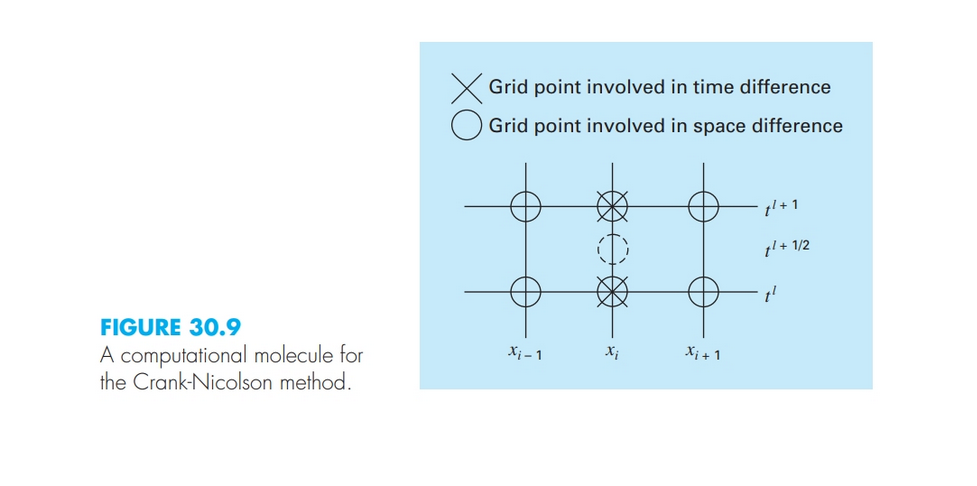

imshow("fig30.9.png") % Computational molecule

Expected Outputs

% T(t,x) --> a series of spatial distributions
% corresponding to the state (Temp.) of the node at each time.

Domain

Inputs

dx = 2; % space step
dt = 0.10; % time step
L = 10; % spatial domain length
x = 0:dx:L; % space vector, each element represents a node in the x-direction
tMax = 100; % temporal domain bound
t = 0:dt:tMax; % time vector

Constants

% Aluminum rod constants
kPrime = 0.49; % cal/(s*cm*degC), thermal conductivity of material, a measure of its ability to conduct heat.
C = 0.2174; % cal/(g*degC), heat capacity
rho = 2.7; % g/cm^3, density
k = kPrime/(rho*C); % cm^2/s, thermal diffusivity of material (sometimes denoted alpha).
% Recall: Thermal diffusivity measures the rate of heat transfer from hot
% to cold.

Stability criterion, see Chapra, p. 852

lambda = k*dt/(dx).^2

lambda = 0.0209

## Conversion Factors & Constants

%-----------------------------------


## Boundary Conditions and Initial Conditions

% Initialize temp matrix, which will be a function of node and time step --
% > this is the solution matrix.
% T(time, space), and counter l (time) and index i (space)
T = zeros(numel(t)+1,numel(x)); % Create a zeros matrix size time domain x spatial domain

% Diff approximations are developed at the midpoint of the time increment
% (see Fig. 30.9)
l = 1; i=2; % The spatial index i is initiated at 2 because i = 1 
% represents the first node in the system and the follow-on calcs will 
% require averaging temp states of three nodes, i.e. i=1, 2, 3.

% Boundary conditions
T(:,1) = 100; % degC, T as a function of all t in the temporal domain and node 1 only, i.e. the left end is fixed at the given value.
T(:,end) = 50; % degC, T will be set to the value for all time to the last (end) node in the system, i.e. the right end is fixed.

% Initial conditions
% temp data, this is the RHS temp vector
intNodes = numel(x)-2; % Number of interior nodes (subtracting two nodes, representing nodes for either end)
Trhs = zeros(numel(t), intNodes); % This both initializes and sets the IC, 
% which happens to be equal to zero for all INTERIOR nodes.

## Convert Units

% ---

## Assumptions

% ---

## Calculate Data

% Create the lambda matrix
lambdaMat = [2*(1+lambda), -lambda, 0, 0;...
             -lambda, 2*(1+lambda), -lambda, 0;...
            0, -lambda, 2*(1+lambda), -lambda;...
            0, 0, -lambda, 2*(1+lambda)];
% Note that the above matrix is tridiagonal.

## Calculations

% Main program

% Calculate the RHS temp vector for every time step, then append the
% temp-node value to the Temp matrix using counter l+1.
% Noting that t=0 sec starts at l=1, and from ICs the interior 
% nodes temp = 0; and t=0.1 sec is l=2.
for l = 1:numel(t)
    % Node 2 temp of Temp matrix, time+1:
    Trhs(l+1, i-1) = lambda*T(l,i-1)+lambda*T(l+1,i-1)+2*(1-lambda)*T(l,i)+lambda*T(l,i+1);
	% Node 3:
    Trhs(l+1, i) = lambda*T(l,i)+2*(1-lambda)*T(l,i+1)-lambda*T(l,i+2);
	% Node 4:
    Trhs(l+1, i+1) = lambda*T(l,i+1)+2*(1-lambda)*T(l,i+2)+lambda*T(l,i+3); 
    % Node 5:
    Trhs(l+1, i+2) = lambda*T(l,i+2)+2*(1-lambda)*T(l,i+3)+lambda*T(l,i+4)+lambda*T(l+1,i+4);
    % Solve the system of equations, outputting Temp for time and node,
    % append the quantities of every interior node to the next time increment
    % in the array.
    T(l+1,i:end-1) = transpose(lambdaMat\transpose(Trhs(l+1,:))); % The output is a row vector
end

%%% 6/26/21 23:19, SATURDAY NIGHT, @ FT. HANCOCK
%%% GOT IT!!!!!!!! ***** %%%%%%% :)

## Step 4: Interpretation of Results

% Final solution matrix
% T(t,x) --> a series of spatial distributions

Tsol = T(1:end-1,:); % To remove the last data point in order for the array sizes to match when plotting.

Plot Results

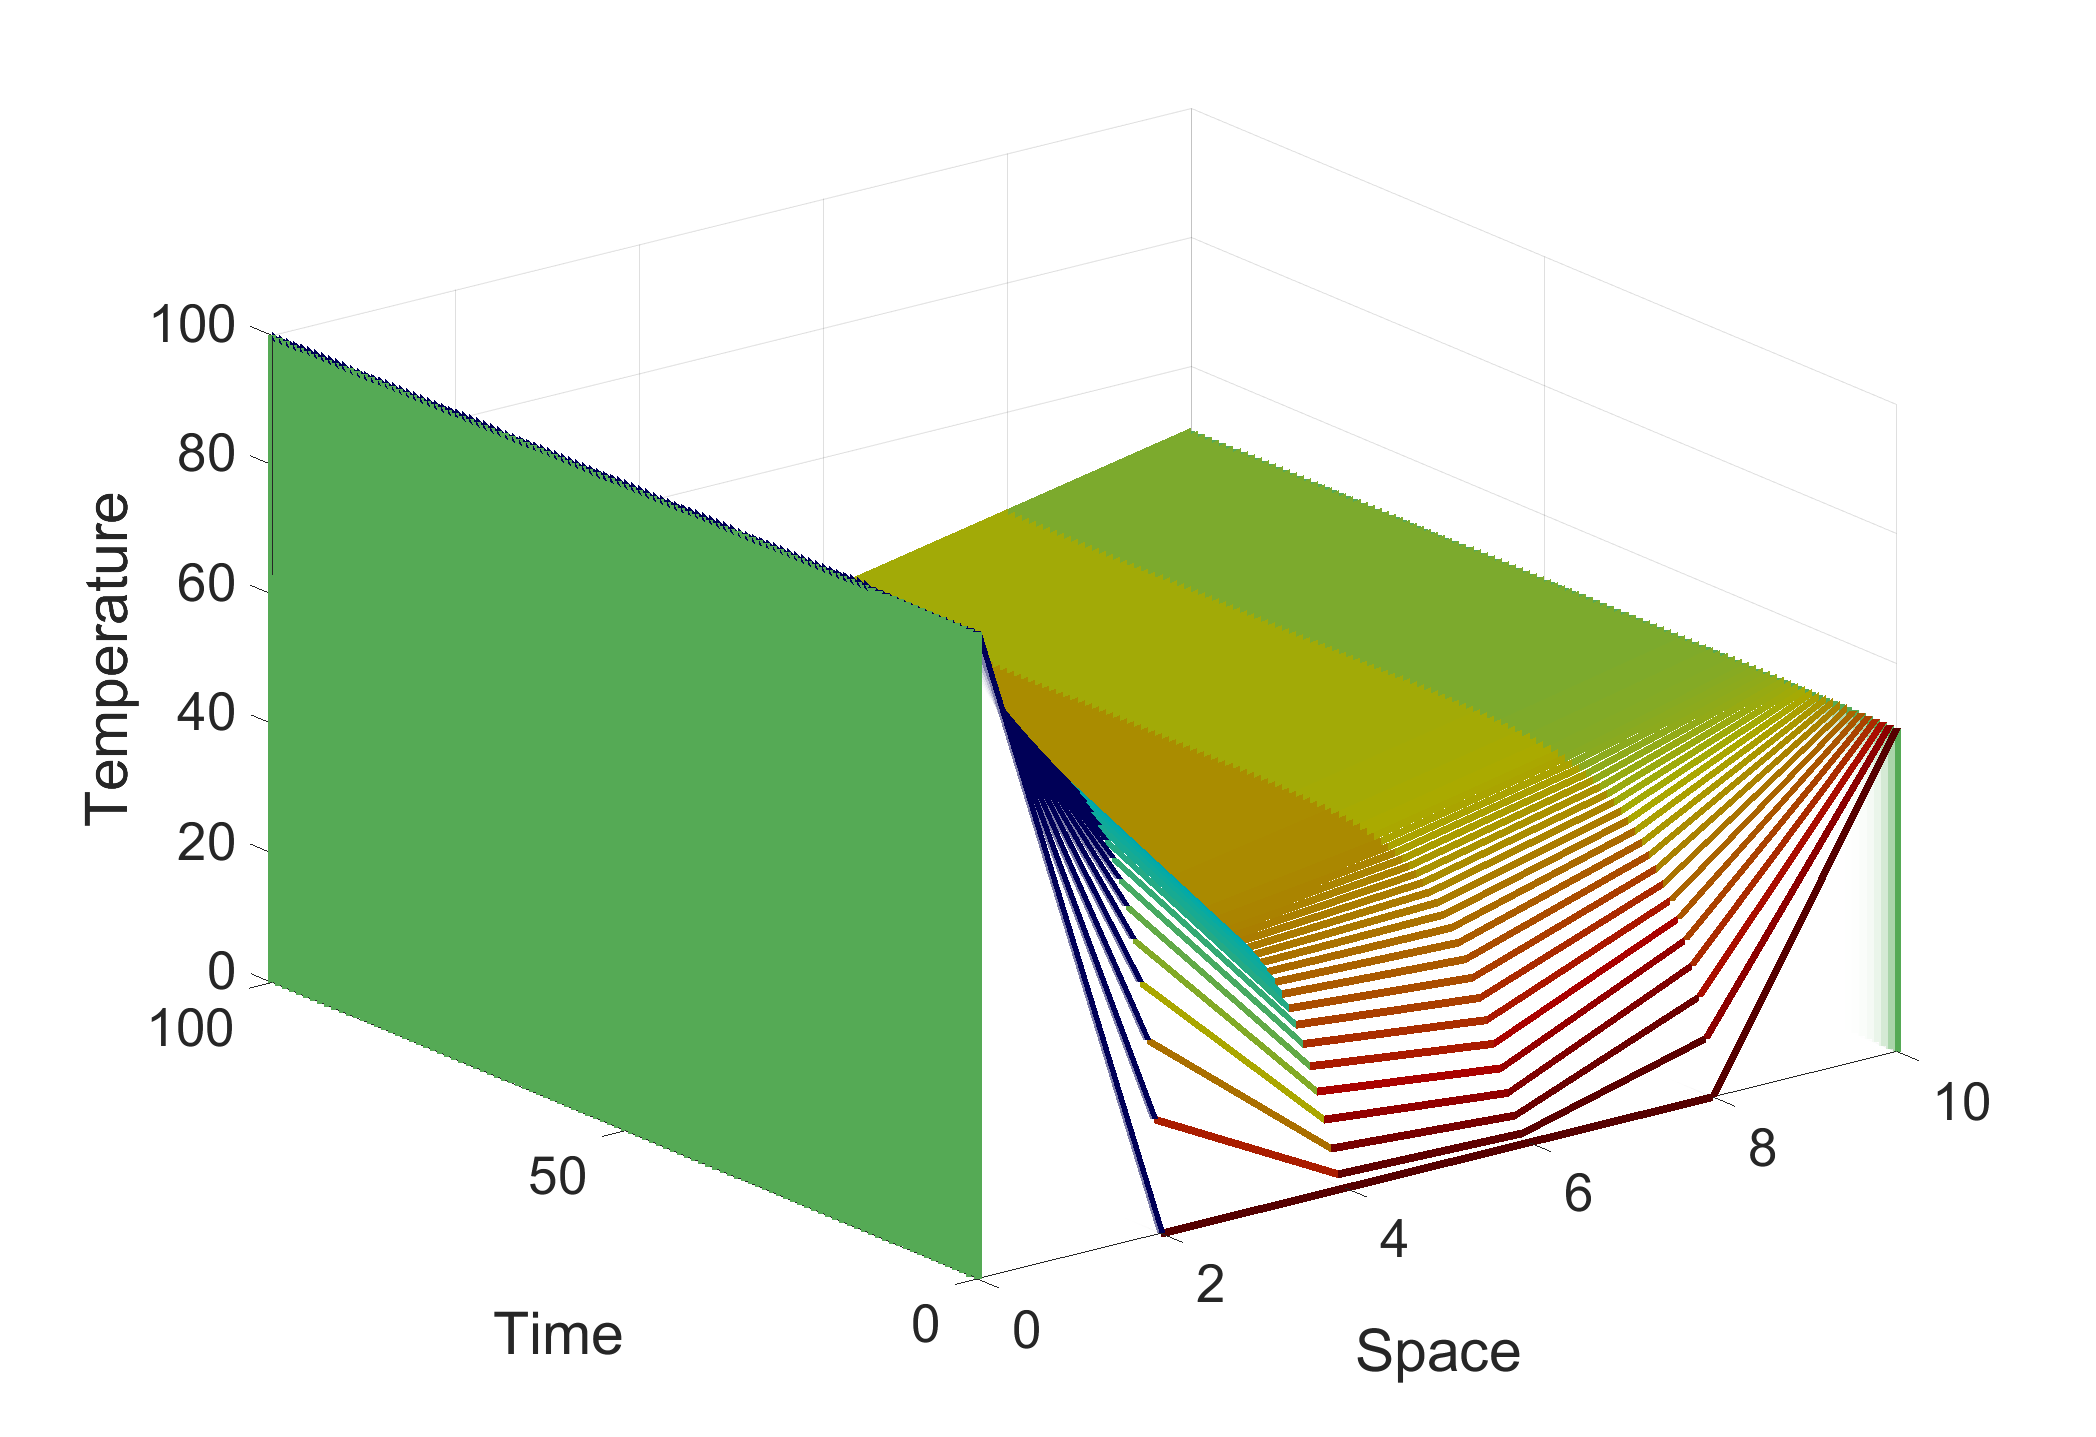

figure;
tTrans = transpose(t); % The array dims must be correct, in order to mesh.
h = waterfall(x,tTrans(1:10:end),Tsol(1:10:end,:)); % The index call is sampling the vector at every 10 units, through end.
set(h,'LineWidth',5,'FaceAlpha',.5);
colormap(flipud(jet)/1.5);
set(gca,'FontSize',32);
xlabel('Space'); ylabel('Time'); zlabel('Temperature');
set(gcf,'Position',[1500 500 1750 1200]);

Discussions of results

Consulting the plot, and focusing on node 2 (element / column 3 in the Temp. solution matrix), x = 4 cm, it is observed that temperature increases at a steady rate, and reaches a steady-state temperature of ~33 degC at approximately 24 seconds after being subjected to the boundary conditions (T = 100 deg C at the left end of the rod, and T = 50 degC at the right end of the rod, both ends are fixed for all time). The same conclusion can be drawn for the other nodes in the system, with transient times also being close to equal.

## Movie

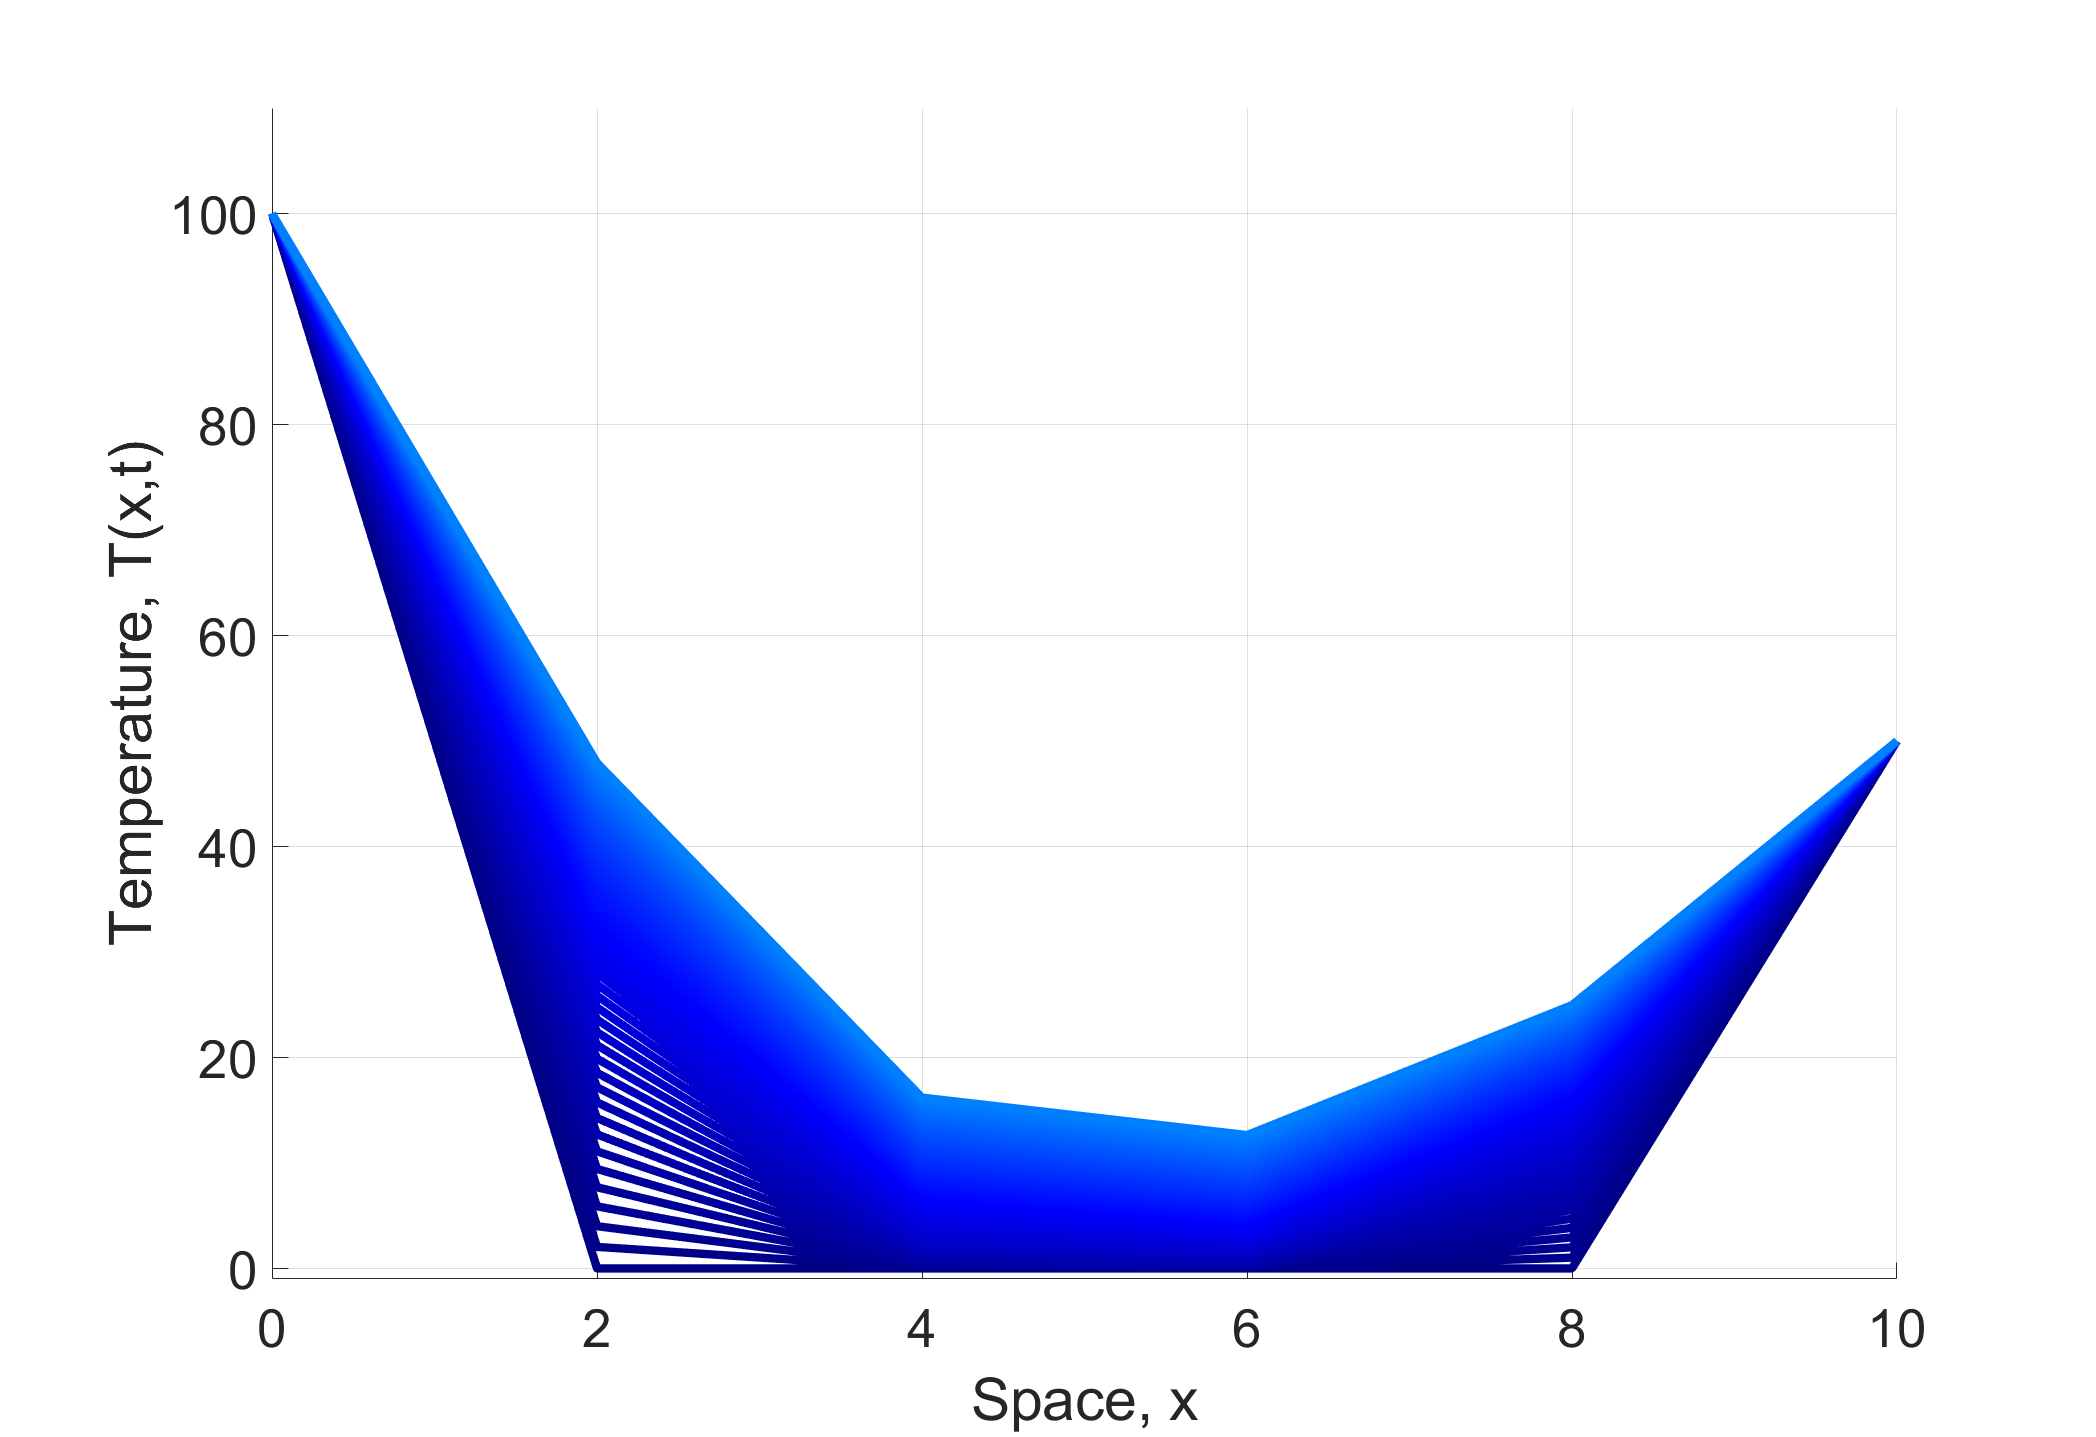

figure;
set(gcf,'Position',[1500 500 1750 1200]) % Sets position at which the figure is shown (isometric).
xlabel('Space, x');
ylabel('Temperature, T(x,t)');
hold on;
set(gca,'FontSize',32);
CC = (colormap(jet(200)));
for j = 1:tMax./2
    T(j,:) = T(j,:); % Grabs the temp value for every time step, for all nodes
    plot(x,T(j,:),'color',CC(j,:),'LineWidth',5);
    ylim([-1 110]); % -1 degC min, to 110 degC max (+10 degC from max in system)
    %set(gcf,'Position',[1500 500 1750 1200])
    hold on, grid on, drawnow
    % Draws the temp distribution across the spatial domain for every time
    % step
end
%set(gcf,'Position',[1500 500 1750 1200]);
hold off;

Crank-Nicolson method, diff. approximations:

dTdt = T(l+1,i) - T(l,i); % (30.12)
d2Tdx2 = 1/2*((T(l, i+1) - 2*T(l, i) + T(l, i-1))/(dx).^2 + (T(l+1, i+1) - 2*T(l+1, i) + T(l+1, i-1)) / (dx).^2); % (30.13)

Diff approx heat conduction equation

diffHeat = k*d2Tdx2 == dTdt;

% End
% Publish by entering ...
% 'publish('DEN417_Rodriguez_HW1.m','pdf')' in the command window